# Inverted Pendulum

clear all, clc, close all
%% OPGELET: ALS JE DIT 1 KEER RUNT BLIJFT LATEX DE STANDAARD OP JE PC TIJDENS EEN SESSIE!
set(groot,'defaultFigurePosition',[0 0 300 300])

## Data

L = 0.3; % pendulum length (m)
M = 0.5; % mass of cart (kg)
m = 0.2; % mass of pendulum (kg)
b = 0.1; % friction coefficient for cart
max_F = 10; % max allowed force (N)
rail_length = 1;  % length of the rail
cart_length = 0.2; % length of the cart
I = 0.006; % traagheidsmoment
g = 9.81; % valversnelling

## Matrices opstellen

N = I*(M+m) + M*m*L^2;
A = [0 1 0 0;
    0 -(I+m*L^2)*b/N m^2*g*L^2/N 0;
    0 0 0 1;
    0 -m*L*b/N m*g*L*(M+m)/N 0];
B = [0;
    (I+m*L^2)/N;
    0;
    m*L/N];
C = [1 0 0 0;
    0 0 1 0];
D = [0;
    0];
states = {'x' 'v' 'theta' 'w'};
inputs = {'u'};
outputs = {'x'; 'theta'};
S = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs);
% Kleine coeff nog naar 0 zetten


## Controleerbaarheid

rank(ctrb(A,B)) == 4

ans = logical
   1


## Observeerbaarheid

rank(obsv(A,C)) == 4

ans = logical
   1


## Discretiseren

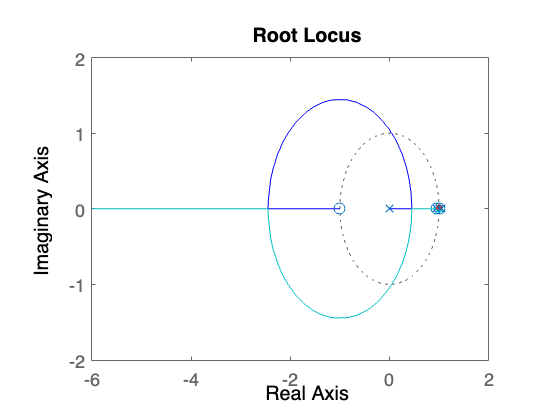

T = 0.01;
Sd = c2d(S,T);
Sdtf = tf(Sd);
ps = pole(Sdtf(2));
zs = zero(Sdtf(2));
Rd = zpk([ps(2:end)],[0,1.04],414,T);
rlocus(Rd*Sd(2))

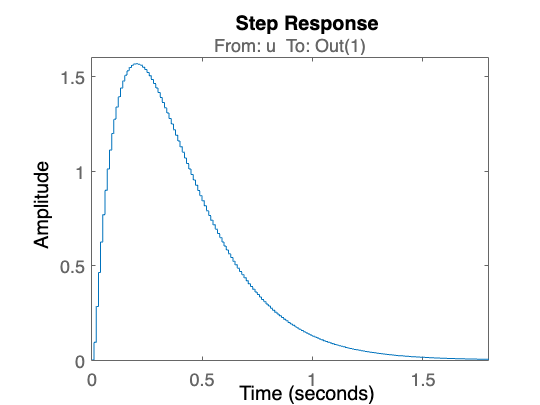

step(feedback(Rd*Sd(2),1))